## Exo Attention Grouped Analysis

- loops through all participants in the data folder assigned by script user

- grabs accuracy and RT of task

- creates a data table/cell array that holds variables of interest

clear;
clc;
% add path where the data lives
prompt = {'Script User'};
answer = inputdlg(prompt);

%if they say nothing do nothing
if isempty(answer)
    return;
else

    user =  answer{1,1};
    [SubjectDirectory] = UserPath(user);
end
addpath(genpath(cd));
addpath(genpath(SubjectDirectory));


% load in the participant assignment table, with all the subject info
ParticipantAssignment = readtable("ParticipantAssignmentsUAB_corr.csv");
ParticipantAssignmentUCR = readtable("ParticipantAssignmentsUCR_corr.csv");
ParticipantAssignment = [ParticipantAssignment; ParticipantAssignmentUCR];


%k is a counter, it counts
k = 1;

tt1count = 1;
tt2count = 1;
tt3count = 1;

% make a blank table, where we'll save all the important variables
DataTableAttention = [];
DataTableAttentionTT1 = [];
DataTableAttentionTT2 = [];
DataTableAttentionTT3 = [];

for z = 5:size(ParticipantAssignment,1)
    subjectID = char(ParticipantAssignment.participant(z));
    % make sure the subject is downloaded to your computer, you won't have
    % everyone because we haven't finished everyone yet
    if exist([SubjectDirectory subjectID]) == 7

        % find the path where the pre-assessment data lives
        directoryPathPre = [SubjectDirectory subjectID '/pre'];


        FileNameAttentionPre = dir([directoryPathPre '/' subjectID 'AttentionPixx*.mat']);
        FileNameAttentionPre = FileNameAttentionPre.name;
        load(FileNameAttentionPre);

        %load in your mixtr, create a variable that holds both RT and percent
        %correct
        mixtr = mixtr(1:length(Att_RT),:);
        Attention = [mixtr rispo(1:length(mixtr))' time_stim(1:length(mixtr))'];




        Left_PRL = Attention(Attention(:,1) == 1,:);
        Right_PRL = Attention(Attention(:,1) == 2,:);

        Left_Congruent = Left_PRL(Left_PRL(:,1) == Left_PRL(:,2),:);
        Left_Incongruent = Left_PRL(Left_PRL(:,1) ~= Left_PRL(:,2),:);
        Right_Congruent = Right_PRL(Right_PRL(:,1) == Right_PRL(:,2),:);
        Right_Incongruent = Right_PRL(Right_PRL(:,1) ~= Right_PRL(:,2),:);


        CorrectTrials = Attention(Attention(:,3)==1,:);
        Correct_Left_PRL = CorrectTrials(CorrectTrials(:,1) == 1,:);
        Correct_Right_PRL = CorrectTrials(CorrectTrials(:,1) == 2,:);


        Correct_Left_Congruent = Correct_Left_PRL(Correct_Left_PRL(:,1) == Correct_Left_PRL(:,2),:);
        Correct_Left_Incongruent = Correct_Left_PRL(Correct_Left_PRL(:,1) ~= Correct_Left_PRL(:,2),:);
        Correct_Right_Congruent = Correct_Right_PRL(Correct_Right_PRL(:,1) == Correct_Right_PRL(:,2),:);
        Correct_Right_Incongruent = Correct_Right_PRL(Correct_Right_PRL(:,1) ~= Correct_Right_PRL(:,2),:);

        Clean_Correct_Attention_Trials_Left_Congruent = Correct_Left_Congruent(Correct_Left_Congruent(:,4) < (mean(Correct_Left_Congruent(:,4) + 3*std(Correct_Left_Congruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Left_Incongruent = Correct_Left_Incongruent(Correct_Left_Incongruent(:,4) < (mean(Correct_Left_Incongruent(:,4) + 3*std(Correct_Left_Incongruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Right_Congruent = Correct_Right_Congruent(Correct_Right_Congruent(:,4) < (mean(Correct_Right_Congruent(:,4) + 3*std(Correct_Right_Congruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Right_Incongruent = Correct_Right_Incongruent(Correct_Right_Incongruent(:,4) < (mean(Correct_Right_Incongruent(:,4) + 3*std(Correct_Right_Incongruent(:,4),'omitnan'))),4);

        Attention_LeftCongruent_RT = mean(Clean_Correct_Attention_Trials_Left_Congruent,'omitnan');
        Attention_LeftIncongruent_RT = mean(Clean_Correct_Attention_Trials_Left_Incongruent,'omitnan');
        Attention_RightCongruent_RT = mean(Clean_Correct_Attention_Trials_Right_Congruent,'omitnan');
        Attention_RightIncongruent_RT = mean(Clean_Correct_Attention_Trials_Right_Incongruent,'omitnan');

        Attention_Left_Congruent_Percent_Correct = length(Correct_Left_Congruent)/length(Left_Congruent)*100;
        Attention_Left_Incongruent_Percent_Correct = length(Correct_Left_Incongruent)/length(Left_Incongruent)*100;
        Attention_Right_Congruent_Percent_Correct = length(Correct_Right_Congruent)/length(Right_Congruent)*100;
        Attention_Right_Incongruent_Percent_Correct = length(Correct_Right_Incongruent)/length(Right_Incongruent)*100;


        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'R'
            TrainedCongruentPC = Attention_Right_Congruent_Percent_Correct;
            TrainedIncongruentPC = Attention_Right_Incongruent_Percent_Correct;
            UntrainedCongruentPC = Attention_Left_Congruent_Percent_Correct;
            UntrainedIncongruentPC = Attention_Left_Incongruent_Percent_Correct;
            TrainedCongruentRT = Attention_RightCongruent_RT;
            TrainedIncongruentRT = Attention_RightIncongruent_RT;
            UntrainedCongruentRT = Attention_LeftCongruent_RT;
            UntrainedIncongruentRT = Attention_LeftIncongruent_RT;
        elseif TrainedSide == 'L'
            TrainedCongruentPC = Attention_Left_Congruent_Percent_Correct;
            TrainedIncongruentPC = Attention_Left_Incongruent_Percent_Correct;
            UntrainedCongruentPC = Attention_Right_Congruent_Percent_Correct;
            UntrainedIncongruentPC = Attention_Right_Incongruent_Percent_Correct;
            TrainedCongruentRT = Attention_LeftCongruent_RT;
            TrainedIncongruentRT = Attention_LeftIncongruent_RT;
            UntrainedCongruentRT = Attention_RightCongruent_RT;
            UntrainedIncongruentRT = Attention_RightIncongruent_RT;
        else
        end

        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            DataTableAttentionTT1{tt1count,1} = subjectID;
            DataTableAttentionTT1{tt1count,2} = TrainedCongruentPC;
            DataTableAttentionTT1{tt1count,3} = TrainedIncongruentPC;
            DataTableAttentionTT1{tt1count,4} = UntrainedCongruentPC;
            DataTableAttentionTT1{tt1count,5} = UntrainedIncongruentPC;
            DataTableAttentionTT1{tt1count,6} = TrainedCongruentRT;
            DataTableAttentionTT1{tt1count,7} = TrainedIncongruentRT;
            DataTableAttentionTT1{tt1count,8} = UntrainedCongruentRT;
            DataTableAttentionTT1{tt1count,9} = UntrainedIncongruentRT;
        

        elseif TrainingType == '2'
            DataTableAttentionTT2{tt2count,1} = subjectID;
            DataTableAttentionTT2{tt2count,2} = TrainedCongruentPC;
            DataTableAttentionTT2{tt2count,3} = TrainedIncongruentPC;
            DataTableAttentionTT2{tt2count,4} = UntrainedCongruentPC;
            DataTableAttentionTT2{tt2count,5} = UntrainedIncongruentPC;
            DataTableAttentionTT2{tt2count,6} = TrainedCongruentRT;
            DataTableAttentionTT2{tt2count,7} = TrainedIncongruentRT;
            DataTableAttentionTT2{tt2count,8} = UntrainedCongruentRT;
            DataTableAttentionTT2{tt2count,9} = UntrainedIncongruentRT;
            

        elseif TrainingType == '3'
            DataTableAttentionTT3{tt3count,1} = subjectID;
            DataTableAttentionTT3{tt3count,2} = TrainedCongruentPC;
            DataTableAttentionTT3{tt3count,3} = TrainedIncongruentPC;
            DataTableAttentionTT3{tt3count,4} = UntrainedCongruentPC;
            DataTableAttentionTT3{tt3count,5} = UntrainedIncongruentPC;
            DataTableAttentionTT3{tt3count,6} = TrainedCongruentRT;
            DataTableAttentionTT3{tt3count,7} = TrainedIncongruentRT;
            DataTableAttentionTT3{tt3count,8} = UntrainedCongruentRT;
            DataTableAttentionTT3{tt3count,9} = UntrainedIncongruentRT;
           
        else
        end

        DataTableAttention{k,1} = subjectID;
        DataTableAttention{k,2} = TrainedCongruentPC;
        DataTableAttention{k,3} = TrainedIncongruentPC;
        DataTableAttention{k,4} = UntrainedCongruentPC;
        DataTableAttention{k,5} = UntrainedIncongruentPC;
        DataTableAttention{k,6} = TrainedCongruentRT;
        DataTableAttention{k,7} = TrainedIncongruentRT;
        DataTableAttention{k,8} = UntrainedCongruentRT;
        DataTableAttention{k,9} = UntrainedIncongruentRT;

% Column 1 = subjectID
% Column 2/10 = trained congruent accuracy
% Column 3/11 = trained incongruent accuracy
% Column 4/12 = untrained congruent accuracy
% Column 5/13 = untrained incongruent accuracy
% Column 6/14 = trained congruent RT
% Column 7/15 = trained incongruent RT
% Column 8/16 = untrained congruent RT
% COlumn 9/17 = untrained incongruent RT


        clearvars -except DataTableAttention SubjectDirectory DataTableAttentionTT1 DataTableAttentionTT2 DataTableAttentionTT3 subjectID ParticipantAssignment z k tt1count tt2count tt3count

        directoryPathPost = [SubjectDirectory subjectID '/post'];
        FileNameAttentionPost = dir([directoryPathPost '/' subjectID 'AttentionPixx*.mat']);
        FileNameAttentionPost = FileNameAttentionPost.name;

        load(FileNameAttentionPost);



        % same with post
        directoryPathPost = [SubjectDirectory subjectID '/post'];
        FileNameAttentionPost = dir([directoryPathPost '/' subjectID 'AttentionPixx*.mat']);
        FileNameAttentionPost = FileNameAttentionPost.name;

        load(FileNameAttentionPost);
        %load in your mixtr, create a variable that holds both RT and percent
        %correct
        mixtr = mixtr(1:length(Att_RT),:);
        Attention = [mixtr rispo(1:length(mixtr))' time_stim(1:length(mixtr))'];




        Left_PRL = Attention(Attention(:,1) == 1,:);
        Right_PRL = Attention(Attention(:,1) == 2,:);

        Left_Congruent = Left_PRL(Left_PRL(:,1) == Left_PRL(:,2),:);
        Left_Incongruent = Left_PRL(Left_PRL(:,1) ~= Left_PRL(:,2),:);
        Right_Congruent = Right_PRL(Right_PRL(:,1) == Right_PRL(:,2),:);
        Right_Incongruent = Right_PRL(Right_PRL(:,1) ~= Right_PRL(:,2),:);


        CorrectTrials = Attention(Attention(:,3)==1,:);
        Correct_Left_PRL = CorrectTrials(CorrectTrials(:,1) == 1,:);
        Correct_Right_PRL = CorrectTrials(CorrectTrials(:,1) == 2,:);


        Correct_Left_Congruent = Correct_Left_PRL(Correct_Left_PRL(:,1) == Correct_Left_PRL(:,2),:);
        Correct_Left_Incongruent = Correct_Left_PRL(Correct_Left_PRL(:,1) ~= Correct_Left_PRL(:,2),:);
        Correct_Right_Congruent = Correct_Right_PRL(Correct_Right_PRL(:,1) == Correct_Right_PRL(:,2),:);
        Correct_Right_Incongruent = Correct_Right_PRL(Correct_Right_PRL(:,1) ~= Correct_Right_PRL(:,2),:);

        Clean_Correct_Attention_Trials_Left_Congruent = Correct_Left_Congruent(Correct_Left_Congruent(:,4) < (mean(Correct_Left_Congruent(:,4) + 3*std(Correct_Left_Congruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Left_Incongruent = Correct_Left_Incongruent(Correct_Left_Incongruent(:,4) < (mean(Correct_Left_Incongruent(:,4) + 3*std(Correct_Left_Incongruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Right_Congruent = Correct_Right_Congruent(Correct_Right_Congruent(:,4) < (mean(Correct_Right_Congruent(:,4) + 3*std(Correct_Right_Congruent(:,4),'omitnan'))),4);
        Clean_Correct_Attention_Trials_Right_Incongruent = Correct_Right_Incongruent(Correct_Right_Incongruent(:,4) < (mean(Correct_Right_Incongruent(:,4) + 3*std(Correct_Right_Incongruent(:,4),'omitnan'))),4);

        Attention_LeftCongruent_RT = mean(Clean_Correct_Attention_Trials_Left_Congruent,'omitnan');
        Attention_LeftIncongruent_RT = mean(Clean_Correct_Attention_Trials_Left_Incongruent,'omitnan');
        Attention_RightCongruent_RT = mean(Clean_Correct_Attention_Trials_Right_Congruent,'omitnan');
        Attention_RightIncongruent_RT = mean(Clean_Correct_Attention_Trials_Right_Incongruent,'omitnan');

        Attention_Left_Congruent_Percent_Correct = length(Correct_Left_Congruent)/length(Left_Congruent)*100;
        Attention_Left_Incongruent_Percent_Correct = length(Correct_Left_Incongruent)/length(Left_Incongruent)*100;
        Attention_Right_Congruent_Percent_Correct = length(Correct_Right_Congruent)/length(Right_Congruent)*100;
        Attention_Right_Incongruent_Percent_Correct = length(Correct_Right_Incongruent)/length(Right_Incongruent)*100;


        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'R'
            TrainedCongruentPC = Attention_Right_Congruent_Percent_Correct;
            TrainedIncongruentPC = Attention_Right_Incongruent_Percent_Correct;
            UntrainedCongruentPC = Attention_Left_Congruent_Percent_Correct;
            UntrainedIncongruentPC = Attention_Left_Incongruent_Percent_Correct;
            TrainedCongruentRT = Attention_RightCongruent_RT;
            TrainedIncongruentRT = Attention_RightIncongruent_RT;
            UntrainedCongruentRT = Attention_LeftCongruent_RT;
            UntrainedIncongruentRT = Attention_LeftIncongruent_RT;
        elseif TrainedSide == 'L'
            TrainedCongruentPC = Attention_Left_Congruent_Percent_Correct;
            TrainedIncongruentPC = Attention_Left_Incongruent_Percent_Correct;
            UntrainedCongruentPC = Attention_Right_Congruent_Percent_Correct;
            UntrainedIncongruentPC = Attention_Right_Incongruent_Percent_Correct;
            TrainedCongruentRT = Attention_LeftCongruent_RT;
            TrainedIncongruentRT = Attention_LeftIncongruent_RT;
            UntrainedCongruentRT = Attention_RightCongruent_RT;
            UntrainedIncongruentRT = Attention_RightIncongruent_RT;
        else
        end

        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            % DataTableAttentionTT1{tt1count,1} = subjectID;
            DataTableAttentionTT1{tt1count,10} = TrainedCongruentPC;
            DataTableAttentionTT1{tt1count,11} = TrainedIncongruentPC;
            DataTableAttentionTT1{tt1count,12} = UntrainedCongruentPC;
            DataTableAttentionTT1{tt1count,13} = UntrainedIncongruentPC;
            DataTableAttentionTT1{tt1count,14} = TrainedCongruentRT;
            DataTableAttentionTT1{tt1count,15} = TrainedIncongruentRT;
            DataTableAttentionTT1{tt1count,16} = UntrainedCongruentRT;
            DataTableAttentionTT1{tt1count,17} = UntrainedIncongruentRT;
             tt1count = tt1count + 1;

        elseif TrainingType == '2'
            % DataTableAttentionTT2{tt2count,1} = subjectID;
            DataTableAttentionTT2{tt2count,10} = TrainedCongruentPC;
            DataTableAttentionTT2{tt2count,11} = TrainedIncongruentPC;
            DataTableAttentionTT2{tt2count,12} = UntrainedCongruentPC;
            DataTableAttentionTT2{tt2count,13} = UntrainedIncongruentPC;
            DataTableAttentionTT2{tt2count,14} = TrainedCongruentRT;
            DataTableAttentionTT2{tt2count,15} = TrainedIncongruentRT;
            DataTableAttentionTT2{tt2count,16} = UntrainedCongruentRT;
            DataTableAttentionTT2{tt2count,17} = UntrainedIncongruentRT;
            tt2count = tt2count + 1;

        elseif TrainingType == '3'
            % DataTableAttentionTT3{tt3count,1} = subjectID;
            DataTableAttentionTT3{tt3count,10} = TrainedCongruentPC;
            DataTableAttentionTT3{tt3count,11} = TrainedIncongruentPC;
            DataTableAttentionTT3{tt3count,12} = UntrainedCongruentPC;
            DataTableAttentionTT3{tt3count,13} = UntrainedIncongruentPC;
            DataTableAttentionTT3{tt3count,14} = TrainedCongruentRT;
            DataTableAttentionTT3{tt3count,15} = TrainedIncongruentRT;
            DataTableAttentionTT3{tt3count,16} = UntrainedCongruentRT;
            DataTableAttentionTT3{tt3count,17} = UntrainedIncongruentRT;
             tt3count = tt3count + 1;
        else
        end

        DataTableAttention{k,10} = TrainedCongruentPC;
        DataTableAttention{k,11} = TrainedIncongruentPC;
        DataTableAttention{k,12} = UntrainedCongruentPC;
        DataTableAttention{k,13} = UntrainedIncongruentPC;
        DataTableAttention{k,14} = TrainedCongruentRT;
        DataTableAttention{k,15} = TrainedIncongruentRT;
        DataTableAttention{k,16} = UntrainedCongruentRT;
        DataTableAttention{k,17} = UntrainedIncongruentRT;



        k  = k + 1;
        clearvars -except  DataTableAttention SubjectDirectory DataTableAttentionTT1 DataTableAttentionTT2 DataTableAttentionTT3 ParticipantAssignment k z tt1count tt2count tt3count
    else
    end
end

% Column 1 = subjectID
% Column 2/10 = trained congruent accuracy
% Column 3/11 = trained incongruent accuracy
% Column 4/12 = untrained congruent accuracy
% Column 5/13 = untrained incongruent accuracy
% Column 6/14 = trained congruent RT
% Column 7/15 = trained incongruent RT
% Column 8/16 = untrained congruent RT
% COlumn 9/17 = untrained incongruent RT

columnNames =  {'Subject ID', 'Pre-Training_Congruent_PC_TRAINED','Pre-Training_Incongruent_PC_TRAINED','Pre-Training_Congruent_PC_UNTRAINED','Pre-Training_Incongruent_PC_UNTRAINED','Pre-Training_Congruent_RT_TRAINED','Pre-Training_Incongruent_RT_TRAINED','Pre-Training_Congruent_RT_UNTRAINED','Pre-Training_Incongruent_RT_UNTRAINED','Pre-Training_Congruent_PC_TRAINED','Post-Training_Incongruent_PC_TRAINED','Post-Training_Congruent_PC_UNTRAINED','Post-Training_Incongruent_PC_UNTRAINED','Post-Training_Congruent_RT_TRAINED','Post-Training_Incongruent_RT_TRAINED','Post-Training_Congruent_RT_UNTRAINED','Post-Training_Incongruent_RT_UNTRAINED','Training Type'};
DataTableExo_table = cell2table(DataTableAttention,'VariableNames',columnNames);
writetable(DataTableExo_table, [SubjectDirectory 'DataTableExoAttn.csv']);

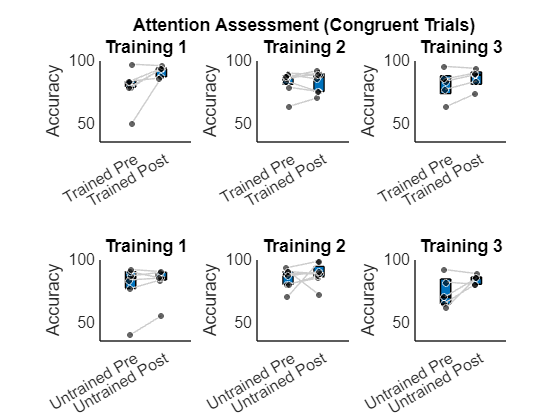


condition_names = {'Trained Pre', 'Trained Post','Untrained Pre', 'Untrained Post'};
f14 = figure;
subplot(2, 3, 1)


AttPCConTrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,2}});
AttPCConTrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,10}});


j1 = daboxplot(AttPCConTrainedTT1,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 1'])
ylim([35 100])


subplot(2, 3, 2)
AttPCConTrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,2}});
AttPCConTrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,10}});


j2 = daboxplot(AttPCConTrainedTT2,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title(['Attention Assessment (Congruent Trials)' newline 'Training 2'])
ylim([35 100])


subplot(2, 3, 3)
AttPCConTrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,2}});
AttPCConTrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,10}});


j2 = daboxplot(AttPCConTrainedTT3,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 3'])
ylim([35 100])

subplot(2, 3, 4)


AttPCConUntrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,4}});
AttPCConUntrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,12}});


j1 = daboxplot(AttPCConUntrainedTT1,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 1'])
ylim([35 100])

subplot(2, 3, 5)
AttPCConUntrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,4}});
AttPCConUntrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,12}});


j2 = daboxplot(AttPCConUntrainedTT2,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 2'])
ylim([35 100])

subplot(2, 3, 6)
AttPCConUntrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,4}});
AttPCConUntrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,12}});


j3 = daboxplot(AttPCConUntrainedTT3,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 3'])
ylim([35 100])

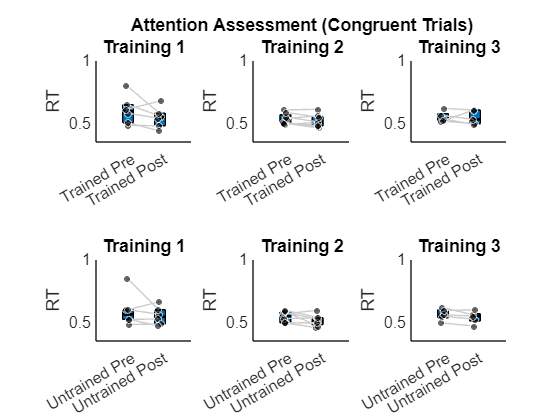

f14 = figure;
subplot(2, 3, 1)


AttRTConTrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,6}});
AttRTConTrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,14}});


j1 = daboxplot(AttRTConTrainedTT1,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 1'])
ylim([0.35 1])


subplot(2, 3, 2)
AttRTConTrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,6}});
AttRTConTrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,14}});


j2 = daboxplot(AttRTConTrainedTT2,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title(['Attention Assessment (Congruent Trials)' newline 'Training 2'])
ylim([0.35 1])


subplot(2, 3, 3)
AttRTConTrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,6}});
AttRTConTrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,14}});


j2 = daboxplot(AttRTConTrainedTT3,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 3'])
ylim([0.35 1])

subplot(2, 3, 4)


AttRTConUntrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,8}});
AttRTConUntrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,16}});


j1 = daboxplot(AttRTConUntrainedTT1,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 1'])
ylim([0.35 1])

subplot(2, 3, 5)
AttRTConUntrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,8}});
AttRTConUntrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,16}});


j2 = daboxplot(AttRTConUntrainedTT2,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 2'])
ylim([0.35 1])

subplot(2, 3, 6)
AttRTConUntrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,8}});
AttRTConUntrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,16}});


j3 = daboxplot(AttRTConUntrainedTT3,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 3'])
ylim([0.35 1])

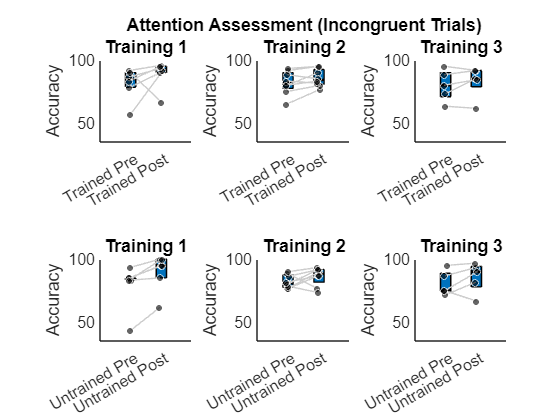

f14 = figure;
subplot(2, 3, 1)


AttPCIncTrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,3}});
AttPCIncTrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,11}});


j1 = daboxplot(AttPCIncTrainedTT1,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 1'])
ylim([35 100])


subplot(2, 3, 2)
AttPCIncTrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,3}});
AttPCIncTrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,11}});


j2 = daboxplot(AttPCIncTrainedTT2,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title(['Attention Assessment (Incongruent Trials)' newline 'Training 2'])
ylim([35 100])


subplot(2, 3, 3)
AttPCIncTrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,3}});
AttPCIncTrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,11}});


j2 = daboxplot(AttPCIncTrainedTT3,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 3'])
ylim([35 100])

subplot(2, 3, 4)


AttPCIncUntrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,5}});
AttPCIncUntrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,13}});


j1 = daboxplot(AttPCIncUntrainedTT1,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 1'])
ylim([35 100])

subplot(2, 3, 5)
AttPCIncUntrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,5}});
AttPCIncUntrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,13}});


j2 = daboxplot(AttPCIncUntrainedTT2,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 2'])
ylim([35 100])

subplot(2, 3, 6)
AttPCIncUntrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,5}});
AttPCIncUntrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,13}});


j3 = daboxplot(AttPCIncUntrainedTT3,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Accuracy')
title([newline 'Training 3'])
ylim([35 100])

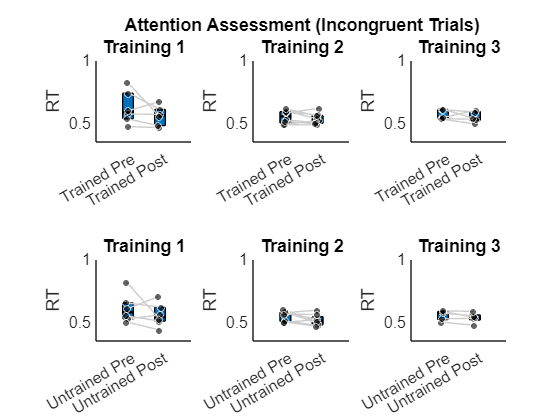

f14 = figure;
subplot(2, 3, 1)


AttRTIncTrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,7}});
AttRTIncTrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,15}});


j1 = daboxplot(AttRTIncTrainedTT1,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 1'])
ylim([0.35 1])


subplot(2, 3, 2)
AttRTIncTrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,7}});
AttRTIncTrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,15}});


j2 = daboxplot(AttRTIncTrainedTT2,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title(['Attention Assessment (Incongruent Trials)' newline 'Training 2'])
ylim([0.35 1])


subplot(2, 3, 3)
AttRTIncTrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,7}});
AttRTIncTrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,15}});


j2 = daboxplot(AttRTIncTrainedTT3,'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 3'])
ylim([0.35 1])

subplot(2, 3, 4)


AttRTIncUntrainedTT1(:,1) = cell2mat({DataTableAttentionTT1{:,9}});
AttRTIncUntrainedTT1(:,2) = cell2mat({DataTableAttentionTT1{:,17}});


j1 = daboxplot(AttRTIncUntrainedTT1,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 1'])
ylim([0.35 1])

subplot(2, 3, 5)
AttRTIncUntrainedTT2(:,1) = cell2mat({DataTableAttentionTT2{:,9}});
AttRTIncUntrainedTT2(:,2) = cell2mat({DataTableAttentionTT2{:,17}});


j2 = daboxplot(AttRTIncUntrainedTT2,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 2'])
ylim([0.35 1])

subplot(2, 3, 6)
AttRTIncUntrainedTT3(:,1) = cell2mat({DataTableAttentionTT3{:,9}});
AttRTIncUntrainedTT3(:,2) = cell2mat({DataTableAttentionTT3{:,17}});


j3 = daboxplot(AttRTIncUntrainedTT3,'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT')
title([newline 'Training 3'])
ylim([0.35 1])